
data = [0, 0.02, 0.04, 0.06, 0.08, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 0.95, 1.0;
     0, 0.134, 0.23, 0.304, 0.365, 0.418, 0.579, 0.665, 0.729, 0.779, 0.825, 0.87, 0.915, 0.958, 0.979, 1];

x = data(1, :); 
y = data(2, :); 

plot(x, y, 'ro', 'MarkerSize', 6, 'DisplayName', 'Data');
hold on;


eqn = 'a*x/(1 + b*x + c*(x^2))';


initialGuess = [1, 1, 1]; % random start point

f = fit(x', y', eqn, 'StartPoint', initialGuess); %fitting equation

disp('Fitted Parameters:');

Fitted Parameters:


disp(f);

     General model:
     f(x) = a*x/(1 + b*x + c*(x^2))
     Coefficients (with 95% confidence bounds):
       a =       7.967  (7.812, 8.122)
       b =       9.411  (9.122, 9.7)
       c =      -2.438  (-2.599, -2.278)


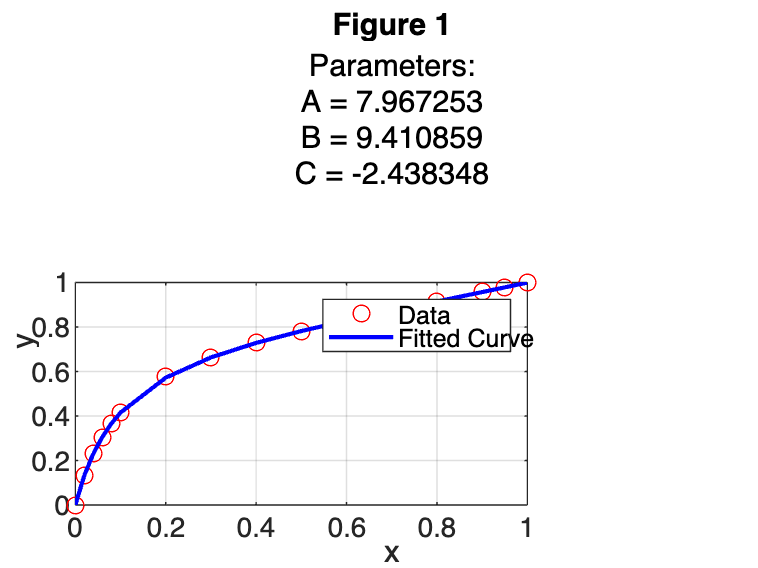

params = coeffvalues(f);
a = params(1);
b = params(2);
c = params(3);
figure(1);
plot_title = sprintf('Parameters:\nA = %f\nB = %f\nC = %f', a, b, c);
fitted_y = feval(f, x);     %for plotting the curve


plot(x, fitted_y, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Curve');
legend('show');
title('Figure 1', plot_title)
xlabel('x');
ylabel('y');
grid on;
hold off;

nt = 4.1400

Total number of trays required: 5


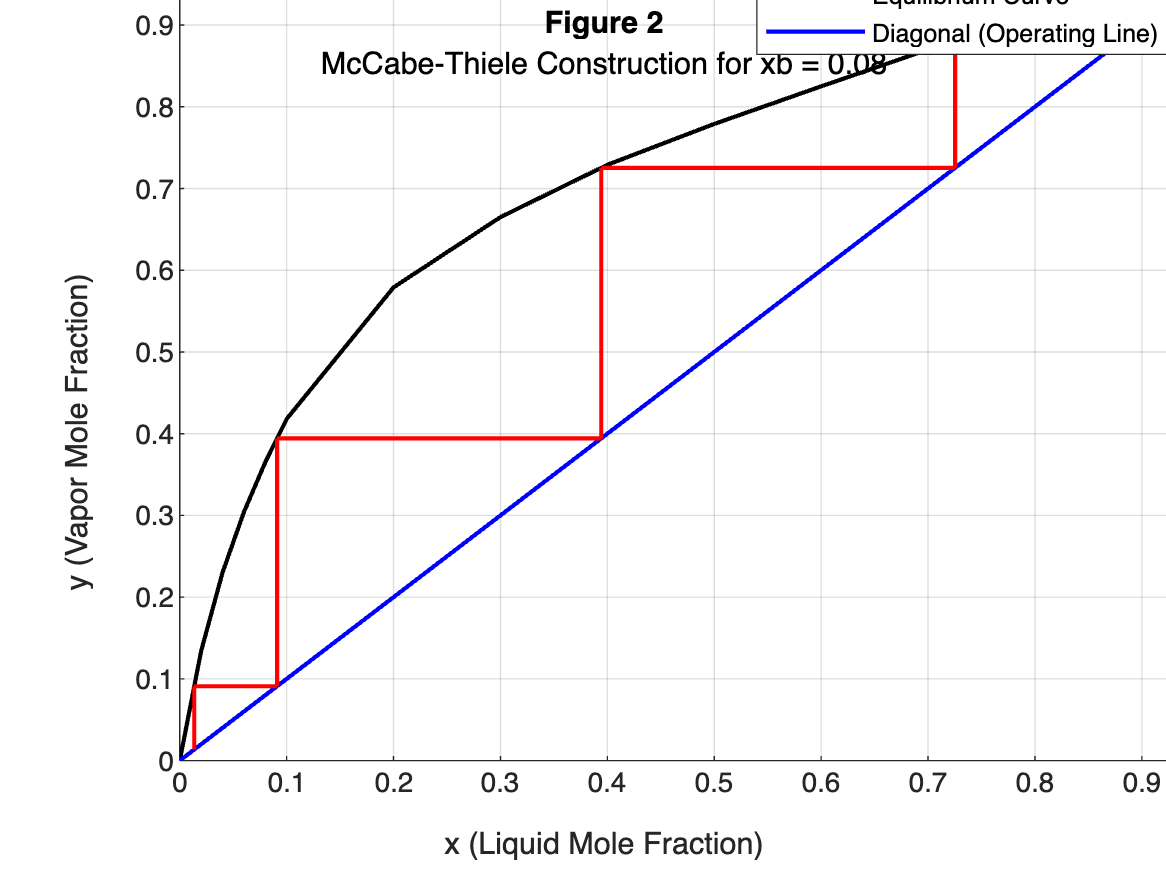

nt = 4.6600

Total number of trays required: 5


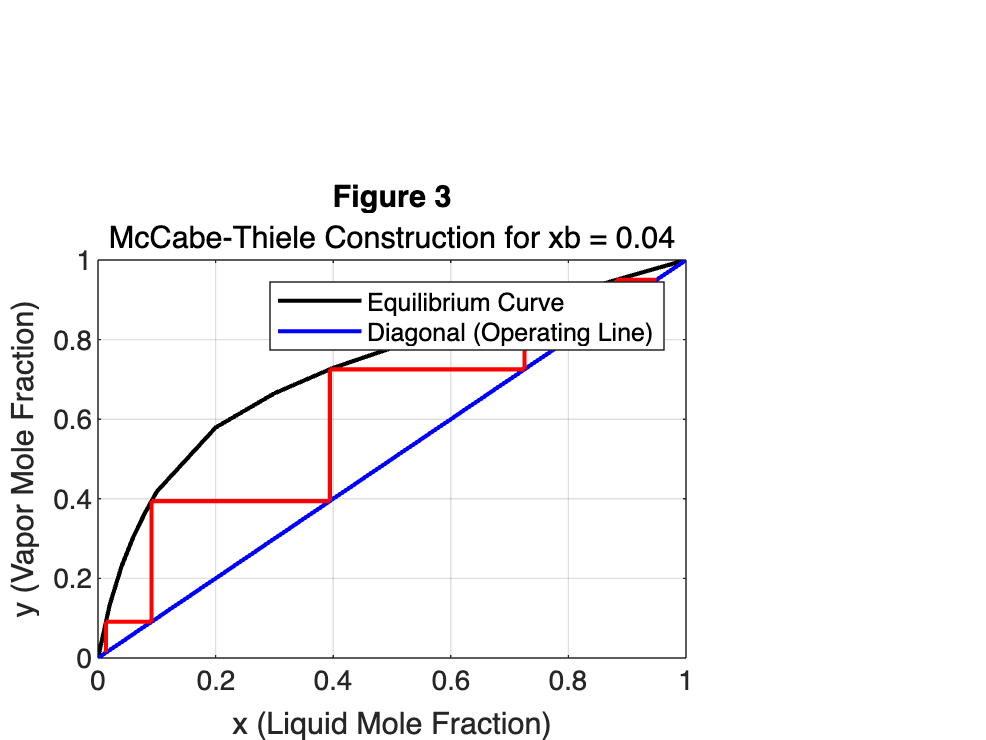



xd = 0.95;  % Distillate composition 
xb_values = [0.08, 0.04];  % Bottom composition calculated using 1 - xw

 
for i = 1:length(xb_values)
  figure (i+1);
  plot(x, y, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Equilibrium Curve') % plotting the eqbm curve
  hold on;
  plot(x, x, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Diagonal (Operating Line)'); % diagonal (operating line in this case of ideal distillation)
  grid on;
  X = xd; %initialising start points on operating line
  Y = xd;
  nt = -1; % initialising no. of trays
    while X >=xb_values(i)
    Xold = X;
    Yold = Y;
    X = interp1(y, x, Yold, 'linear', 'extrap'); 
    Y = X;
    nt = nt + 1;
    plot([Xold X], [Yold Yold], 'r-', 'LineWidth', 1.5); %horizontal line
    plot([X X], [Yold Y], 'r-', 'LineWidth', 1.5);   %vertical line
    end
 hold off;
 nt = round((nt+(Yold-xb_values(i))/(Yold-Y)),2)
 req_t = ceil(nt);  %rounding up nt for required no. of trays
 disp(['Total number of trays required: ', num2str(req_t)]);
 legend(["Equilibrium Curve", "Diagonal (Operating Line)"]);
 xlabel('x (Liquid Mole Fraction)');
 ylabel('y (Vapor Mole Fraction)');
 title(['Figure ', num2str(i+1)], ['McCabe-Thiele Construction for xb = ', num2str(xb_values(i))]);
 grid on;
end